# Taller 13

### 11/17/2022 2022-01S

#### Métodos Númericos

#### *Resumen sobre la semana 10 y 11*

*Notas para el uso de MATLAB:*

- Frente a las operaciones de númericas tenemos 2 definiciones distintas y es importante separarlas, las operaciones $+-*\;/$, son directas matriciales, en cambio las prefijadas con ${\prime \ldotp }^{\prime }$, son *element-wise*, o sea se realizan en cada uno de los elementos del argumento entregado a la función. Importante en la notación con @

- Si se necesita conocer información sobre un método o sobre alguna rutina, es comando `help ``rutina` resulta bastante útil.

- **Otros recursos sobre manejo de MATLAB practicas básicas: ***https://matlabacademy.mathworks.com/es/*

*Recordar documentarse en cada una de las rutinas disponibles del curso y de MATLAB para afrontar distintas situaciones, MATLAB es su aliado.*

### Método del disparo Lineal

#### Unos comentarios frente a los problemas de valor en la frontera

Los problemas de valor en la frontera son ecuaciones diferenciales, normalmente estas condiciones se ven en cuando se presentan derivadas parciales, y son ecuaciones donde solo se especifica las condiciones del contorno de la forma a hallar, se conocen como condiciones tipo *Dirichlet*

Para afrontar estos problemas, la estrategia que adoptaremos es reescribir el problema de frontera en problemas de valores iniciales, con pendientes adecuadas

#### PVF: Transformación a PVI equivalente

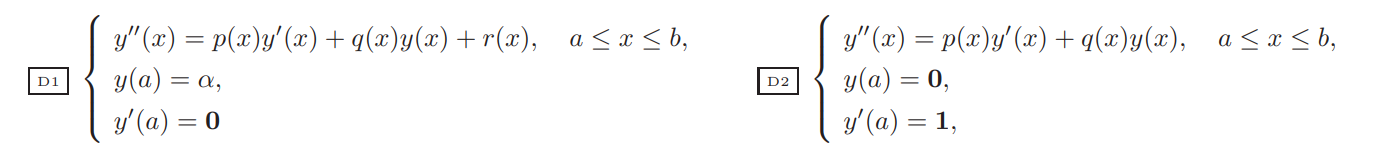

La solución hallada en D1, la notamos como $u\left(x\right)$ y D2 como $v\left(x\right)$, y la consideración de la solución:

`Nota: ``En ingenieria es común afrontar estos problemas de cualquier orden haciendo uso de los métodos de diferencias finitas.`

`Punto 1. ``Consideraciones del uso de MATLAB`

clear
syms f(t, y, dy)

% Definimos la función y los componentes a analizar
f(t, y, dy) = exp(-3*t) * (sin(3*t^3) + atan(y) - exp(-dy^2));
fy(t, y) = diff(f, y);
fdy(t, dy) = diff(f, dy);

% Consideramos el máximo de exp(-3t), y reemplazamos para reducir el orden
% de la función a analizar
g(dy) = fdy(-1, dy);
dg(dy) = diff(g, dy);

% Hallamos los valores extremos y evaluamos
dg(dy) = collect(dg, exp(-dy^2)); c = sqrt(1/2);
dg(c);

g(c), vpa(g(c), 5)

`Punto 2. ``Resolvamos un PVF`

clear
syms f(x, y, dy)
syms s(x)

f(x, y, dy) = 1 / s(x) * (-1/3 * log(x) - 4*x*dy - 3*x^2*y)
D1 = f(x, y, dy)
D2 = 1 / s(x) * (- 4*x*dy - 3*x^2*y)
U = [1.5 1.7694 2.2990 3.1144 4.3435 6.2154];
V = [0 .0922 .1492 .2126 .3010 .4331];

Y = U + (6.2 - U(end)) / V(end) * V;

`Punto 3. ``Consideremos el siguiente PVF`

clear

$$ans = \sqrt{2}\,{\mathrm{e}}^{5/2}$$

$$ans = 17.229$$

syms f(x, y, dy)

f(x, y, dy) = -1 + log(x)/x + 3/x^2 * y + 1/x * dy
F = @(x, U) [U(2), -1 + log(x)./x + ...
                    3./x.^2 .* U(1) + 1./x .* U(2)];

D1 = @(x, U) F(x, U);

$$f(x, y, dy) = -\frac{\frac{\log\left(x\right)}{3}+4\,\mathrm{dy}\,x+3\,x^{2}\,y}{s\left(x\right)}$$

D2 = @(x, U) [U(2), 3./x.^2 .* U(1) + 1./x .* U(2)];

$$D1 = -\frac{\frac{\log\left(x\right)}{3}+4\,\mathrm{dy}\,x+3\,x^{2}\,y}{s\left(x\right)}$$

$$D2 = -\frac{3\,y\,x^{2}+4\,\mathrm{dy}\,x}{s\left(x\right)}$$

[T, U] = rks4(D1, 1, 2, [0, 0], 10); U = U(:, 1);
[~, V] = rks4(D2, 1, 2, [0, 1], 10); V = V(:, 1);

Y = U + (0 - U(end)) / V(end) * V; Y'
LS = linshtMod(D1, D2, 1, 2, 0, 0, 10); LS(:, 2)'
[T, U] = eulerMods(D1, 1, 2, [0, 0], 10); U = U(:, 1);
[~, V] = eulerMods(D2, 1, 2, [0, 1], 10); V = V(:, 1);

Y = U + (0 - U(end)) / V(end) * V; Y'

$$f(x, y, dy) = \frac{\log\left(x\right)}{x}+\frac{\mathrm{dy}}{x}+\frac{3\,y}{x^{2}}-1$$

ans =          0    0.0280    0.0497    0.0655    0.0755    0.0796    0.0775    0.0688    0.0534    0.0306         0


ans =          0    0.0277    0.0494    0.0651    0.0751    0.0792    0.0771    0.0685    0.0531    0.0304         0


ans =          0    0.0278    0.0495    0.0652    0.0752    0.0792    0.0771    0.0686    0.0532    0.0304         0
